## Error #1: Wrong readout of temperature measurement from AM2320 sensor.

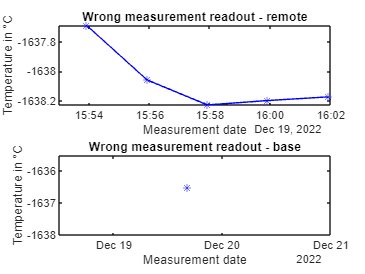

close all;
readChannelID = 1906177;
fieldID1 = 1;
fieldID2 = 2;


readAPIKey = 'LACZILGHBEHGM53L';

% Read first data variable
[data1,time1] = thingSpeakRead(readChannelID, 'Field', fieldID1, 'NumPoints', 398, 'ReadKey', readAPIKey);

% Read second data variable
[data2,time2] = thingSpeakRead(readChannelID, 'Field', fieldID2, 'NumPoints', 398, 'ReadKey', readAPIKey);

%% Process Data
wrongIndices1 = [372, 374, 376, 378, 380];
wrongIndices2 = 392;
subplot(2,1,1);
plot(time1(wrongIndices1), data1(wrongIndices1), 'b*-');
title("Wrong measurement readout - remote");
ylabel("Temperature in °C");
xlabel("Measurement date");

subplot(2,1,2);
plot(time2(wrongIndices2), data2(wrongIndices2), 'b*-');
title("Wrong measurement readout - base");
ylabel("Temperature in °C");
xlabel("Measurement date");

## Error #2. Incorrect first pressure measurement

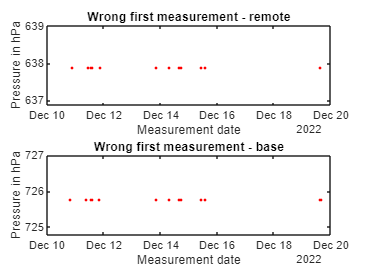

close all;
[data3,time3] = thingSpeakRead(readChannelID, 'Field', 3, 'NumPoints', 398, 'ReadKey', readAPIKey);
[data4,time4] = thingSpeakRead(readChannelID, 'Field', 4, 'NumPoints', 398, 'ReadKey', readAPIKey);

wrongPress1 = data3 < 900;
wrongPress2 = data4 < 900;

subplot(2,1,1);
plot(time3(wrongPress1), data3(wrongPress1), 'r.');
title("Wrong first measurement - remote");
ylabel("Pressure in hPa");
xlabel("Measurement date");

subplot(2,1,2);
plot(time4(wrongPress2), data4(wrongPress2), 'r.');
title("Wrong first measurement - base");
ylabel("Pressure in hPa");
xlabel("Measurement date");

## Success #1. Full 2.5 hours of consecutive measurements.

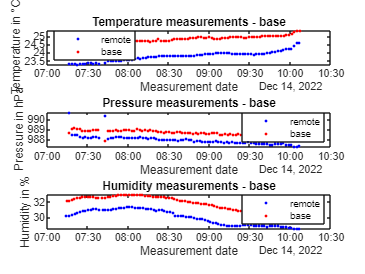

close all;
[data5,time5] = thingSpeakRead(readChannelID, 'Field', 5, 'NumPoints', 398, 'ReadKey', readAPIKey);
[data6,time6] = thingSpeakRead(readChannelID, 'Field', 6, 'NumPoints', 398, 'ReadKey', readAPIKey);

goodIdx1 = [124:197, 199:299];
goodIdx2 = 124:299;
goodIdx3 = [125:150, 152:197, 199:299];
goodIdx4 = [124,126:149, 151:299];
goodIdx5 = [124:197, 199:299];
goodIdx6 = 124:299;

% removed outliers
%TODO: remove these outliers
subplot(3,1,1);
plot(time1(goodIdx1), data1(goodIdx1), 'b.');
title("Temperature measurements - remote");
ylabel("Temperature in °C");
xlabel("Measurement date");
hold on
% subplot(3,1,2);
plot(time2(goodIdx2), data2(goodIdx2), 'r.');
title("Temperature measurements - base");
ylabel("Temperature in °C");
xlabel("Measurement date");
legend("remote", "base", Location="best");
hold off;


subplot(3,1,2);
plot(time3(goodIdx3), data3(goodIdx3), 'b.');
title("Pressure measurements - remote");
ylabel("Pressure in hPa");
xlabel("Measurement date");
hold on;
% subplot(3,2,4);
plot(time4(goodIdx4), data4(goodIdx4), 'r.');
title("Pressure measurements - base");
ylabel("Pressure in hPa");
xlabel("Measurement date");
legend("remote", "base", Location="best");
hold off;

subplot(3,1,3);
plot(time5(goodIdx5), data5(goodIdx5), 'b.');
title("Humidity measurements - remote");
ylabel("Humidity in %");
xlabel("Measurement date");
hold on;
% subplot(3,2,6);
plot(time6(goodIdx6), data6(goodIdx6), 'r.');
title("Humidity measurements - base");
ylabel("Humidity in %");
xlabel("Measurement date");
legend("remote", "base", Location="best");
hold off

## Radio communication - good

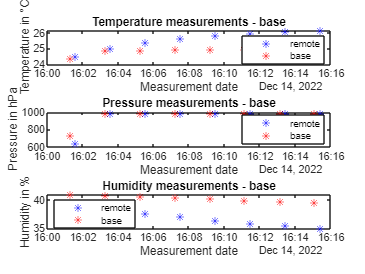

close all;
goodIdx = 300:315;
subplot(3,1,1);
plot(time1(goodIdx), data1(goodIdx), 'b*');
title("Temperature measurements - remote");
ylabel("Temperature in °C");
xlabel("Measurement date");
hold on
plot(time2(goodIdx), data2(goodIdx), 'r*');
title("Temperature measurements - base");
ylabel("Temperature in °C");
xlabel("Measurement date");
legend("remote", "base", Location="best");
hold off;

subplot(3,1,2);
plot(time3(goodIdx), data3(goodIdx), 'b*');
title("Pressure measurements - remote");
ylabel("Pressure in hPa");
xlabel("Measurement date");
hold on;
plot(time4(goodIdx), data4(goodIdx), 'r*');
title("Pressure measurements - base");
ylabel("Pressure in hPa");
xlabel("Measurement date");
legend("remote", "base", Location="best");
hold off;

subplot(3,1,3);
plot(time5(goodIdx), data5(goodIdx), 'b*');
title("Humidity measurements - remote");
ylabel("Humidity in %");
xlabel("Measurement date");
hold on;
plot(time6(goodIdx), data6(goodIdx), 'r*');
title("Humidity measurements - base");
ylabel("Humidity in %");
xlabel("Measurement date");
legend("remote", "base", Location="best");
hold off

## Radio communication - bad

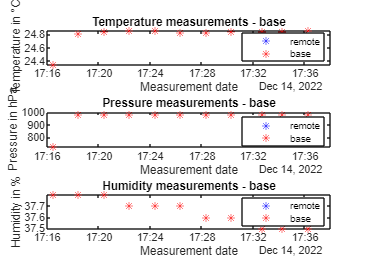

close all;
goodIdx = 316:326;
subplot(3,1,1);
plot(time1(goodIdx), data1(goodIdx), 'b*');
title("Temperature measurements - remote");
ylabel("Temperature in °C");
xlabel("Measurement date");
hold on
plot(time2(goodIdx), data2(goodIdx), 'r*');
title("Temperature measurements - base");
ylabel("Temperature in °C");
xlabel("Measurement date");
legend("remote", "base", Location="best");
hold off;

subplot(3,1,2);
plot(time3(goodIdx), data3(goodIdx), 'b*');
title("Pressure measurements - remote");
ylabel("Pressure in hPa");
xlabel("Measurement date");
hold on;
plot(time4(goodIdx), data4(goodIdx), 'r*');
title("Pressure measurements - base");
ylabel("Pressure in hPa");
xlabel("Measurement date");
legend("remote", "base", Location="best");
hold off;

subplot(3,1,3);
plot(time5(goodIdx), data5(goodIdx), 'b*');
title("Humidity measurements - remote");
ylabel("Humidity in %");
xlabel("Measurement date");
hold on;
plot(time6(goodIdx), data6(goodIdx), 'r*');
title("Humidity measurements - base");
ylabel("Humidity in %");
xlabel("Measurement date");
legend("remote", "base", Location="best");
hold off

## Wifi - bad connection

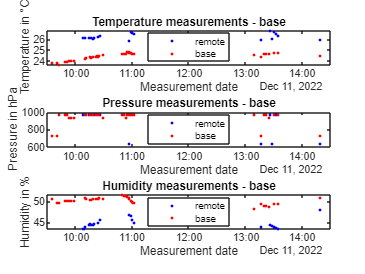

close all;
goodIdx = [47:65, 67:106];
subplot(3,1,1);
plot(time1(goodIdx), data1(goodIdx), 'b.');
title("Temperature measurements - remote");
ylabel("Temperature in °C");
xlabel("Measurement date");
hold on
plot(time2(goodIdx), data2(goodIdx), 'r.');
title("Temperature measurements - base");
ylabel("Temperature in °C");
xlabel("Measurement date");
legend("remote", "base", Location="best");
hold off;

subplot(3,1,2);
plot(time3(goodIdx), data3(goodIdx), 'b.');
title("Pressure measurements - remote");
ylabel("Pressure in hPa");
xlabel("Measurement date");
hold on;
plot(time4(goodIdx), data4(goodIdx), 'r.');
title("Pressure measurements - base");
ylabel("Pressure in hPa");
xlabel("Measurement date");
legend("remote", "base", Location="best");
hold off;

subplot(3,1,3);
plot(time5(goodIdx), data5(goodIdx), 'b.');
title("Humidity measurements - remote");
ylabel("Humidity in %");
xlabel("Measurement date");
hold on;
plot(time6(goodIdx), data6(goodIdx), 'r.');
title("Humidity measurements - base");
ylabel("Humidity in %");
xlabel("Measurement date");
legend("remote", "base", Location="best");
hold off